## Q1:Systemic arterial model- baseline vs arteriosclerosis

% QUESTION 1 %%%%%
%Parameters
Psa0= 100; % initial systemic arterial pressure (mmHg)
Rs= 17.5;  % systemic resistance (mmHg/(L/min))
T= 0.0125;  % heart period (min)
ts= 0.005; %systole duration (min)
tmax=0.002;% time max flow (min)
Qmax=14.14;% max aortic flow (L/min)
dt=0.0001; % time step (min)
Csa0= 0.001; %baseline systemic arterial compliance (L/mmHg)
Csa_f= Csa0/2; % arteriosclerosis: reduced by factor of 2

% Time-25 beats
tv=0:dt:25*T;

%% Aortic flow, same 
QAo=zeros(size(tv));
for k = 1:length(tv)-1
    QAo(k) = Qtriangwave(tv(k),Qmax,T,ts,tmax);
end
QAo(end)=QAo(end-1);

%% Baseline simulation, regular Csa
Psa_norm=zeros(size(tv));
Psa_norm(1)=Psa0;

for k = 1:length(tv)-1
    Psa_norm(k+1) = Psa_norm(k) + dt*(QAo(k) - Psa_norm(k)/Rs)/Csa0;
end

Vsa_norm=Csa0 * Psa_norm;
Qs_norm =Psa_norm / Rs;

%% TASK: ARTERIOSCLEROSIS SIMULATION (Csa/2). anything _hard=csa/2
Psa_hard= zeros(size(tv));
Psa_hard(1)= Psa0;

for k = 1:length(tv)-1
    Psa_hard(k+1)= Psa_hard(k) +dt*(QAo(k)- Psa_hard(k)/Rs)/Csa_f;
end

Vsa_hard=Csa_f * Psa_hard;
Qs_hard=Psa_hard / Rs;

%% PRESSURE METRICS FOR LAST HEART BEAT
lastBeatStart =max(tv) - T; %to find when the last heartbeat starts 
idxLast=tv>= lastBeatStart; %to use all the data points for the last heartbeat. 

% Normal
Psyst_norm= max(Psa_norm(idxLast));
Pdiast_norm= min(Psa_norm(idxLast));
Pmean_norm= mean(Psa_norm(idxLast));
Ppulse_norm= Psyst_norm -Pdiast_norm;

% Arteriosclerosis
Psyst_hard= max(Psa_hard(idxLast));
Pdiast_hard= min(Psa_hard(idxLast));
Pmean_hard= mean(Psa_hard(idxLast));
Ppulse_hard= Psyst_hard - Pdiast_hard;

fprintf('\nNORMAL Csa = %.4f L/mmHg\n', Csa0);


NORMAL Csa = 0.0010 L/mmHg


fprintf('Systolic= %.1f mmHg\n', Psyst_norm);

Systolic= 60.9 mmHg


fprintf('Diastolic= %.1f mmHg\n', Pdiast_norm);

Diastolic= 38.4 mmHg


fprintf('Mean= %.1f mmHg\n', Pmean_norm);

Mean= 49.4 mmHg


fprintf('Pulse= %.1f mmHg\n', Ppulse_norm);

Pulse= 22.4 mmHg



fprintf('\nTask:ARTERIOSCLEROSIS (Csa/2 = %.4f L/mmHg)\n', Csa_f);


Task:ARTERIOSCLEROSIS (Csa/2 = 0.0005 L/mmHg)


fprintf('Systolic= %.1f mmHg\n', Psyst_hard);

Systolic= 72.7 mmHg


fprintf('Diastolic= %.1f mmHg\n', Pdiast_hard);

Diastolic= 28.8 mmHg


fprintf('Mean= %.1f mmHg\n', Pmean_hard);

Mean= 49.3 mmHg


fprintf('Pulse= %.1f mmHg\n\n', Ppulse_hard);

Pulse= 43.9 mmHg



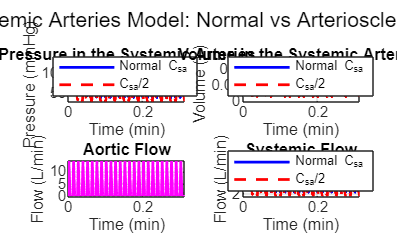


%% Plotting data
figure('Position',[100 100 1000 600]);
sgtitle('Systemic Arteries Model: Normal vs Arteriosclerosis');

% Pressure
subplot(2,2,1);
plot(tv,Psa_norm,'b','LineWidth',1.5); hold on
plot(tv,Psa_hard,'r--','LineWidth',1.5);
grid on
xlabel('Time (min)');
ylabel('Pressure (mmHg)');
title('Pressure in the Systemic Arteries');
legend('Normal C_{sa}','C_{sa}/2','Location','best');

% Volume
subplot(2,2,2);
plot(tv,Vsa_norm,'b','LineWidth',1.5); hold on
plot(tv,Vsa_hard,'r--','LineWidth',1.5);
grid on
xlabel('Time (min)');
ylabel('Volume (L)');
title('Volume in the Systemic Arteries');
legend('Normal C_{sa}','C_{sa}/2','Location','best');

% Aortic flow (same both cases)
subplot(2,2,3);
plot(tv,QAo,'m','LineWidth',1.5);
grid on
xlabel('Time (min)');
ylabel('Flow (L/min)');
title('Aortic Flow');

% Systemic flow
subplot(2,2,4);
plot(tv,Qs_norm,'b','LineWidth',1.5); 
hold on
plot(tv,Qs_hard,'r--','LineWidth',1.5);
grid on
xlabel('Time (min)');
ylabel('Flow (L/min)');
title('Systemic Flow');
legend('Normal C_{sa}','C_{sa}/2','Location','best');

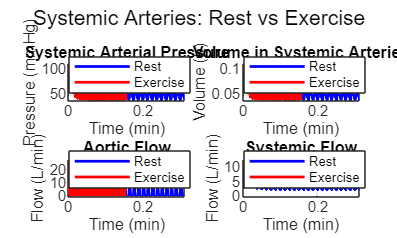

%%%%%%%%%%% Question 2%%%%%%%%%%%%%%
% Parameters 
Psa0= 100; % initial systemic arterial pressure (mmHg)
Rs= 17.5;  % systemic resistance (mmHg/(L/min))
T= 0.0125;  % heart period (min)
ts= 0.005; %systole duration (min)
tmax=0.002;% time max flow (min)
Qmax=14.14;% max aortic flow (L/min)
dt=0.0001; % time step (min)
Csa0= 0.001; %baseline systemic arterial compliance (L/mmHg)

%25beats
tv_rest = 0:dt:25*T;

% Aortic flow at rest)
QAo_rest = zeros(size(tv_rest));
for k = 1:length(tv_rest)-1
    QAo_rest(k) = Qtriangwave(tv_rest(k),Qmax,T,ts,tmax);
end
QAo_rest(end) = QAo_rest(end-1);

% Pressure at rest
Psa_rest = zeros(size(tv_rest));
Psa_rest(1) = Psa0;
for k = 1:length(tv_rest)-1
    Psa_rest(k+1) = Psa_rest(k) + dt*(QAo_rest(k) - Psa_rest(k)/Rs)/Csa;
end

Vsa_rest = Csa * Psa_rest;
Qs_rest  = Psa_rest / Rs;

%%To complete task Rs needs to be reduced by  Rs/2, T,ts,tmax/2 and Qmax adjusted to keep SV
Rs_ex= Rs/2; % lower systemic resistance
T_ex= T/2; % faster HR
ts_ex= ts/2;
tmax_ex= tmax/2;
Qmax_ex=2*Qmax;% keeps volume the same

% 25 beats at exercise HR
tv_ex = 0:dt:25*T_ex;

% Aortic flow druing exercise
QAo_ex = zeros(size(tv_ex));
for k = 1:length(tv_ex)-1
    QAo_ex(k) = Qtriangwave(tv_ex(k),Qmax_ex,T_ex,ts_ex,tmax_ex);
end
QAo_ex(end) =QAo_ex(end-1);

% Pressure druing exercise
Psa_ex = zeros(size(tv_ex));
Psa_ex(1) = Psa0;
for k = 1:length(tv_ex)-1
    Psa_ex(k+1) = Psa_ex(k) + dt*(QAo_ex(k) - Psa_ex(k)/Rs_ex)/Csa;
end

Vsa_ex = Csa * Psa_ex;
Qs_ex  = Psa_ex / Rs_ex;

%Plotting results 

figure('Position',[100 100 1000 600]);
sgtitle('Systemic Arteries: Rest vs Exercise');

% Pressure
subplot(2,2,1);
plot(tv_rest,Psa_rest,'b','LineWidth',1.5); hold on
plot(tv_ex,Psa_ex,'r','LineWidth',1.5);
grid on
xlabel('Time (min)');
ylabel('Pressure (mmHg)');
title('Systemic Arterial Pressure');
legend('Rest','Exercise','Location','best');

% Volume
subplot(2,2,2);
plot(tv_rest,Vsa_rest,'b','LineWidth',1.5); hold on
plot(tv_ex,Vsa_ex,'r','LineWidth',1.5);
grid on
xlabel('Time (min)');
ylabel('Volume (L)');
title('Volume in Systemic Arteries');
legend('Rest','Exercise','Location','best');

% Aortic Flow
subplot(2,2,3);
plot(tv_rest,QAo_rest,'b','LineWidth',1.5); hold on
plot(tv_ex,QAo_ex,'r','LineWidth',1.5);
grid on
xlabel('Time (min)');
ylabel('Flow (L/min)');
title('Aortic Flow');
legend('Rest','Exercise','Location','best');

% Systemic Flow
subplot(2,2,4);
plot(tv_rest,Qs_rest,'b','LineWidth',1.5); 
hold on
plot(tv_ex,Qs_ex,'r','LineWidth',1.5);
grid on
xlabel('Time (min)');
ylabel('Flow (L/min)');
title('Systemic Flow');
legend('Rest','Exercise','Location','best');

%%%%QUESTION 3%%%%%


%% Triangle-wave aortic flow function (same as before)
function Q = Qtriangwave(t,Qmax,T,ts,tmax)
t1 = rem(t,T);
for ii = 1:length(t)
    if t1(ii) <= ts               % systole
        if t1(ii) <= tmax         % upstroke
            Q(ii) = Qmax*t1(ii)/tmax;
        else                      % downstroke
            Q(ii) = Qmax*(ts-t1(ii))/(ts-tmax);
        end
    else                          % diastole
        Q(ii) = 0;
    end
end
end
